Este es un script derivado de un ejemplo de Matlab (Construct and Train a Convolutional Neural Network). Modificado en algunos aspectos particularespara incluir nuevas perspectivas necesarias para la clase.

# Train Network for Image Classification

Load the data as an `ImageDatastore` object. %artificio de matlab para guardar imagenes

digitDatasetPath = './DigitDataset';
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

The datastore contains 10,000 synthetic images of digits from 0 to 9. The images are generated by applying random transformations to digit images created with different fonts. Each digit image is 28-by-28 pixels. The datastore contains an equal number of images per category. 

Display some of the images in the datastore. 

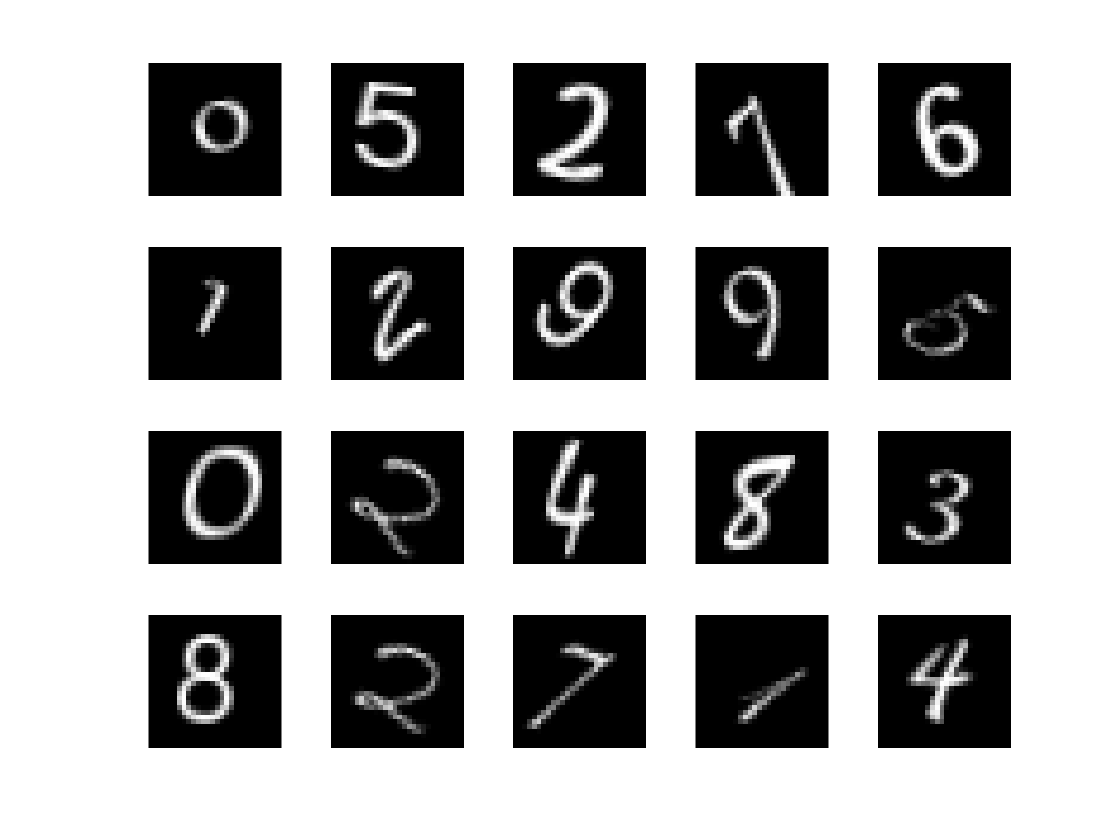

figure
numImages = 10000;
perm = randperm(numImages,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
    drawnow;
end

Divide the datastore so that each category in the training set has 750 images and the testing set has the remaining images from each label. 

numTrainingFiles = 750;
[imdsTrain,imdsTest] = splitEachLabel(imds,numTrainingFiles,'randomize');

`splitEachLabel` splits the image files in `digitData` into two new datastores, `imdsTrain` and `imdsTest`. 

Define the convolutional neural network architecture. 

layers = [ ...
    imageInputLayer([28 28 1])
    convolution2dLayer(5,20) %capa convolucional (tamaño filtro, num filtros)
    reluLayer
    maxPooling2dLayer(2,'Stride',2) %capa de pooling, filtro que se queda con el maximo
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];


Si se quisiese usar una red densa multicapa podría hacerse algo como lo siguiente:

% layers = [
%     imageInputLayer([28 28 1])
%     fullyConnectedLayer(128)
%     reluLayer
%     fullyConnectedLayer(10)
%     softmaxLayer
%     classificationLayer
% ];

Set the options to the default settings for the stochastic gradient descent with momentum. Set the maximum number of epochs at 20, and start the training with an initial learning rate of 0.0001.

options = trainingOptions('sgdm', ...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4, ...
    'Verbose',false, ...
    'Plots','training-progress');

Train the network. 

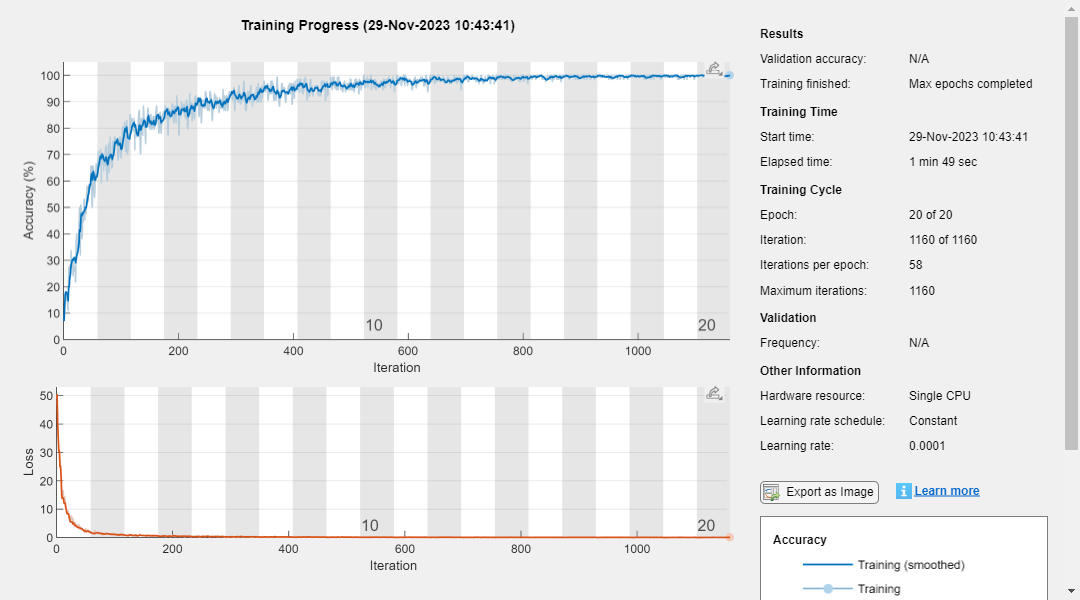

net = trainNetwork(imdsTrain,layers,options);

Run the trained network on the test set, which was not used to train the network, and predict the image labels (digits).

YPred = classify(net,imdsTest);
YTest = imdsTest.Labels;

Calculate the accuracy. The accuracy is the ratio of the number of true labels in the test data matching the classifications from `classify` to the number of images in the test data.

accuracy = sum(YPred == YTest)/numel(YTest)

accuracy = 0.9508

*Copyright 2012 The MathWorks, Inc.*